# Демодуляция ЧМ-сигналов

# Delay Line Detector

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Delay Line Detector

Наиболее простой и распространенный способ частотной демодуляции в SDR называется Delay Line Detector или фазовый дескриминатор. Принцип его работы заключается в оценке мгновенной частоты сигнала за счет вычисления разности фаз между двумя соседними отсчетами.

Будем считать, что прием сигнала осуществляется квадратурным способом. Тогда принятый комплексный продискретизированный сигнал можем представить в виде:


$$s\left\lbrack n\right\rbrack =A_с \cdot \exp^{j\cdot \left(2\pi f_с \mathrm{nT}+2\pi K_f \cdot \sum_{k=-\infty }^n m\left\lbrack k\right\rbrack \right)} =A_с \cdot \exp^{j\cdot \theta \left\lbrack n\right\rbrack } ,$$


где $\mathrm{T}$ - шаг дискретизации, $\mathrm{n}$ - номер отсчета, $\theta \left\lbrack n\right\rbrack$ - фаза сигнала.

Найти разность фаз между двумя последовательными отсчтами можно следующим образом. Берем от задерженного отсчета комплексное сопряжение и умножаем его на текущий отсчет. Результат произведения будет равен:


$$s\left\lbrack n\right\rbrack \cdot s^* \left\lbrack n-1\right\rbrack =A_с \cdot \exp^{j\cdot \theta \left\lbrack n\right\rbrack } \cdot A_с \cdot \exp^{-j\cdot \theta \left\lbrack n-1\right\rbrack } =A_c^2 \cdot \exp^{j\cdot \left(\theta \left\lbrack n\right\rbrack -\theta \left\lbrack n-1\right\rbrack \right)} \ldotp$$


Подставляя в предыдущее уравнение полное выражения для фазы сигнала, получим:


$$s\left\lbrack n\right\rbrack \cdot s^* \left\lbrack n-1\right\rbrack =A_c^2 \cdot \exp^{j\cdot \left(\theta \left\lbrack n\right\rbrack -\theta \left\lbrack n-1\right\rbrack \right)} =A_c^2 \cdot \exp^{j\cdot \left(2\pi K_f \cdot m\left\lbrack k\right\rbrack \right)} \ldotp$$


Если вычислить аргумент от произведения отсчетов, то получим следующий результат:


$$\arg \left\lbrace s\left\lbrack n\right\rbrack \cdot s^* \left\lbrack n-1\right\rbrack \right\rbrace =2\pi K_f \cdot m\left\lbrack k\right\rbrack \ldotp$$


Таким образом, описанная процедура позволяет восстановить масштабированную копию информационного сообщения. Схема приемного устройства имеет вид:

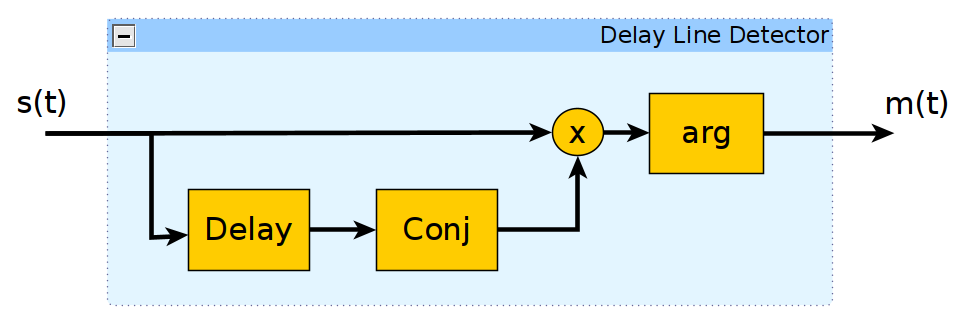

### 2. Демодуляция аудиосообщения

Рассмотрим демодуляцию аудиосообщения с помощью скрипта, реализующего Delay Line Detector.

В файлах Audio_FM_ModIdx_*.wav записаны частотно-модулированные сигналы с различными индексами модуляции. Частота несущей $f_s$ равна 100 kHz, а частота дискретизации $f_s$ = $441$ kHz. Считаем, что прием выполняется квадратурным способ, то есть сигнал имеет вид:


$$s\left(t\right)=A_с \cdot \exp^{j\cdot \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)} \ldotp$$


Для демодуляции информационного сообщения задерживаем полученную пачку (frame) отсчетов на один отсчет и находим от них комплексное сопряжение. Далее вычисляем произведение текущего и задержанного отсчетов и рассчитываем его аргумент. После децимации и удаления постоянной составлющей получаем информационное сообщение.

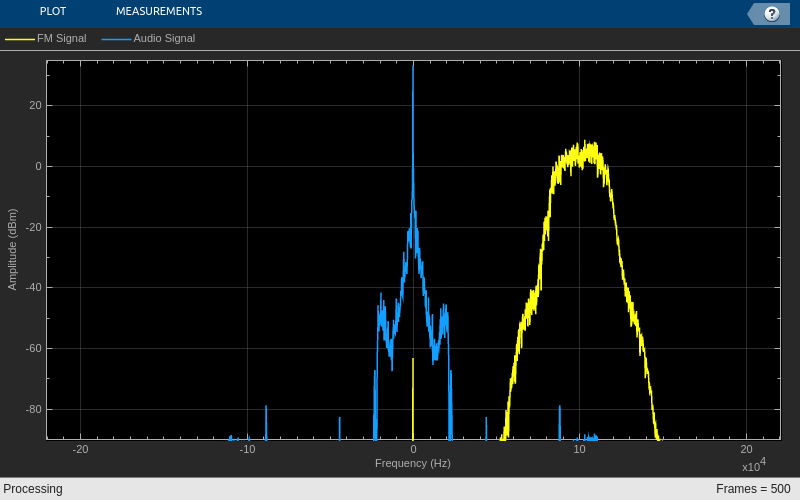

clc; clear; close all;

SignalFrameSize = 10000;          % количество отсчетов чм-сигнала, получаемых за один раз
FramesNumber = 500;               % число обрабатываемых пачек данных
AudioAmp = 0.3;                   % коэффициент усиления аудиосигнала
RateRatio = 10;                   % коэффициент увеличения частоты дискретизации
ModIndex = '1';   % индекс модуляции

% имя считываемого файла
SignalFileName = sprintf('wav/Audio_FM_ModIdx_%s.wav', ModIndex);

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    SignalFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% задержка 
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal', 'Audio Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов ЧМ-сигнала
    FmSignal = AudioReader();
    FmSignal = FmSignal(:,1) + 1j*FmSignal(:,2);
     
    % вычисление разности фаз между отсчетами
    FmSignalDelayed = DelayBlock(FmSignal);
    PhaseDiff = angle(FmSignal .* conj(FmSignalDelayed));

    % понижение частоты дискретизации
    AudioSignal = DownSampler(PhaseDiff);
    
    % убираем постоянную составляющую
    AudioSignal = AudioSignal - mean(AudioSignal);
    
    % формирование итогового сллбщения
    Message = [Message; AudioAmp * AudioSignal];

    % вычисление спектров
    SpectrumData = SpecEstimator([FmSignal PhaseDiff]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

На спектрограмме желтым показан спектр частотно-модулированного сигнала, а синим - спектр восстановленного сообщения.

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что сообщение восстанавливается без искажений.

### 3. Демодуляция FM-радио в Matlab

Ниже представлен скрипт, позволяющий прослушивать FM-радио с помощью RTL-SDR. Настройка на нужную радиостанцию выполняется с помощью переменной Fc, которая задает частоту несущей. Входной сигнал проходит через фильтр нижных частот для выделения нужной радиостанции. Отфильтрованный сигнал поступает на Delay Line Detector. В заключение сигнал децимируется, у него удаляется постоянная составляющая и он подается на звуковую карту. 

clc; clear; close all;
addpath('matlab/demodulation');

Fc = 106.2e6;                % частота несущей в Hz
SignalFs = 1.2e6;            % частота дискретизации RTL-SDR
AudioFs = 48e3;              % частота дискретизации демодулированного аудиосигнала
SignalFrameSize = 512*25;    % количество отсчетов чм-сигнала, получаемых за один раз
FcShift = 200e3;             % частота сдвига после фильтрации
AudioAmp = 0.1;              % коэффициент усиления аудиосигнала

SDRRTL = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency', Fc,...
    'EnableTunerAGC', true,...
    'SampleRate', SignalFs, ...
    'SamplesPerFrame', SignalFrameSize,...
    'OutputDataType', 'double' ...
);

% расчет коэффициентов и создание фильтра нижних частот
Fpass = 110e3;
Fstop = 160e3;
H = Audio_Lowpass_FIR_Coeff(SignalFs, Fpass, Fstop);
LowpassFIR = dsp.FIRFilter(H.Numerator);

% задержка на один отсчет
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% воспроизведение аудио сигнала
AudioSink = audioDeviceWriter(AudioFs);

% запуск симуляции
while(true)
    % получение отсчетов сигнала
    FmSignalData = SDRRTL();
    
    % вычисление спектров и вывод результатов на график
    SpectrumData = SpecEstimator(FmSignalData);
    Plotter(SpectrumData);
    
    % фильтрация
    FilteredData = LowpassFIR(FmSignalData);
    
    % вычисление разности фаз между отсчетами
    FilteredSignalDelayed = DelayBlock(FilteredData);
    PhaseDiff = angle(FilteredData .* conj(FilteredSignalDelayed));
    
    % удаляем постоянную составляющую
    PhaseDiff = PhaseDiff - mean(PhaseDiff);
    
    % уменьшение частоты дискретизации
    AudioData = DownSampler(PhaseDiff);
    
    % проигрывание данных
    AudioSink(AudioData * AudioAmp);
  
end

### 4. Демодуляция FM-радио в Simulink

В файле FM_SDR_Receiver_Delay_Line.slx представлена Simulink-модель, позволяющая прослушивать FM-радио с помощью RTL-SDR. Все преобразования сигнала совпадают с теми, что ранее были описаны в Matlab скрипте.

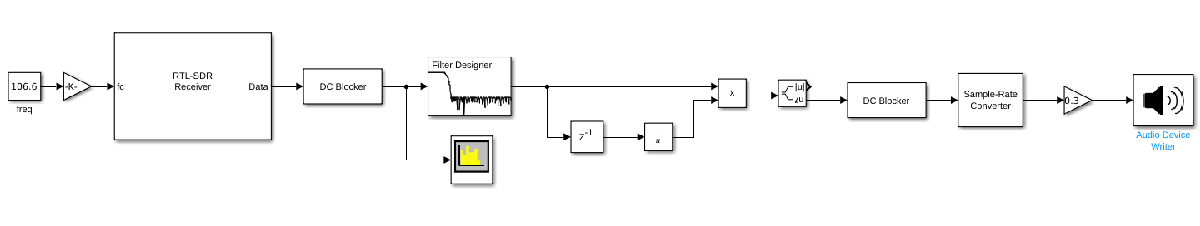

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR